clc
close all
clear all

iex = 2;

%% EXAMPLE 1:  Trapezoidal rule
if iex ==1

end
    % Make an example Parabola
    % y = ax^2 + bx + c
    
    % Input coefficients
    a = -1;
    b = 4;
    c = 0;
    
    % Intialize x
    x = [-1:.01:5];
    
    % Initialize function
    f = @(a,b,c,x) a*x.^2 + b*x + c;
    
    % Call the function and find value of Y at X
    y = f(a,b,c,x);
    
    % Discretize X for summation
    xmin = 0; xmax = 4;
    Nsamples = 33; % Number of points for dividing x (N-1 trapezoids)
    x_sum = linspace(xmin,xmax,Nsamples);
    h = x_sum(2) - x_sum(1);
    
    % Y- points at x for summation
    y_sum = f(a,b,c,x_sum);
    
    % area1=XXX; % key
   area=0;
   for i=1:Nsamples-1
       area =area+(0.5*h)*(y_sum(i)+y_sum(i+1));
   end
   area

area = 10.6563

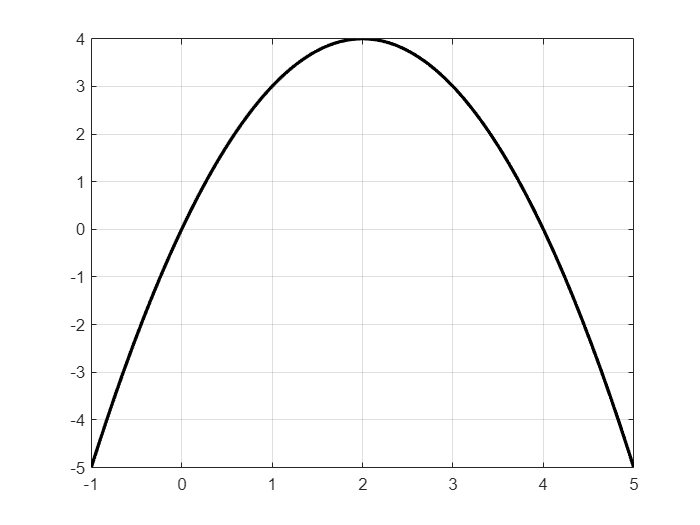

    % plot
    figure
    plot(x,y,'k','LineWidth',2);
    grid on, hold on

   
    % color area under the trapezoid
    for ii = 1:length(x_sum)-1
        area([x_sum(ii) x_sum(ii+1)],[y_sum(ii) y_sum(ii+1)]);
    end

Index in position 1 is invalid. Array indices must be positive integers or logical values.

    
    % plot circluar markers
    for ii = 1:length(x_sum)
        plot([x_sum(ii)],[y_sum(ii)],'o','MarkerFaceColor','r','MarkerEdgeColor','k');
    end
    

